% https://www.mathworks.com/help/comm/ref/qammod.html


## Basic QAM

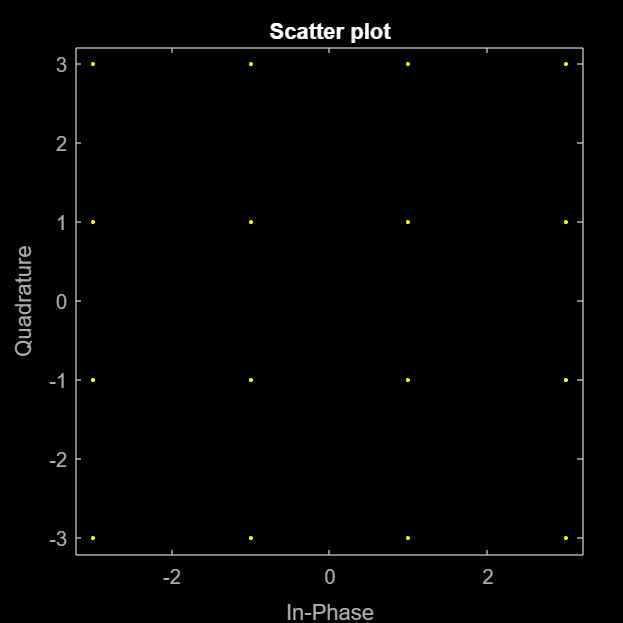

M = 16;
x = (0:M-1)';
% Modulate the data using the qammod function.
y = qammod(x,M); %16x1 complex
scatterplot(y)


% Normalize the modulator output so that it has an average signal power of 1 W.
M = 64;
x = randi([0 M-1],1000,1);%1000x1 double
%Modulate the data. Use the 'UnitAveragePower' name-value pair to set the output signal to have an average power of 1 W.
y = qammod(x,M,'UnitAveragePower',true);%1000x1 complex
%Confirm that the signal has unit average power.
avgPower = mean(abs(y).^2)

avgPower = 1.0061

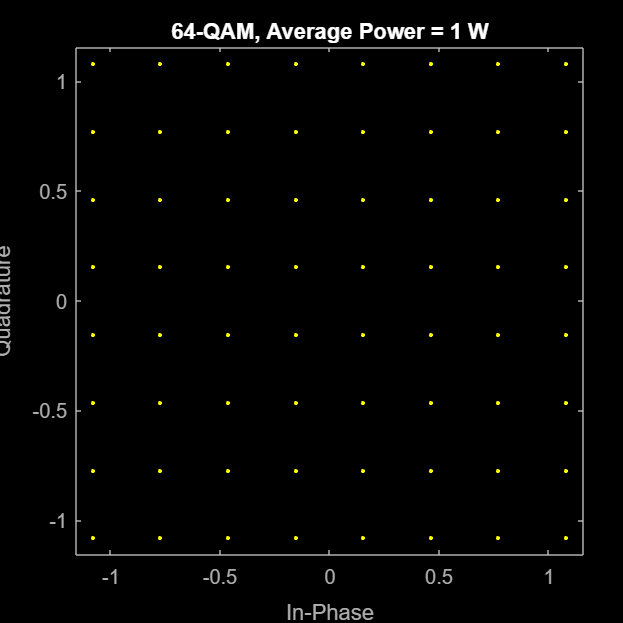

%Plot the resulting constellation.
scatterplot(y)
title('64-QAM, Average Power = 1 W')

## Quadrature Amplitude Modulation with Bit Inputs

M = 64;
k = log2(M); %bitsPerSym
%Create a binary data sequence. When using binary inputs, the number of rows in the input must be an integer multiple of the number of bits per symbol.
numBits = 1000*k

numBits = 6000

data = randi([0 1],1000*k,1);
%Modulate the signal using bit inputs, and set it to have unit average power.
%txSig = qammod(data,M,'bin','InputType','bit','UnitAveragePower',true);
txSig = qammod(data,M,'bin','InputType','bit')

txSig =    3.0000 - 7.0000i
   5.0000 + 5.0000i
  -7.0000 + 7.0000i
   7.0000 + 5.0000i
   5.0000 - 1.0000i
  -7.0000 - 1.0000i
   5.0000 + 1.0000i
   1.0000 - 5.0000i
   1.0000 - 5.0000i
  -3.0000 + 5.0000i


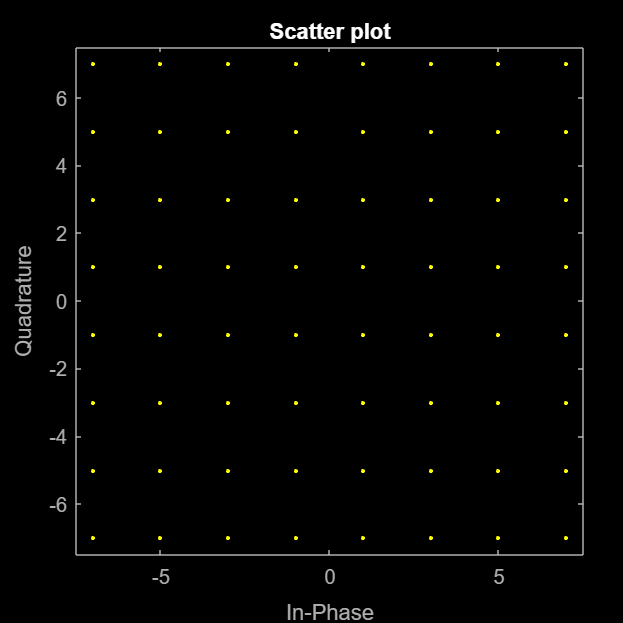

%txSig = qammod(data,M,'bin','InputType','bit','OutputDataType', numerictype(1,16,10));
scatterplot(txSig)

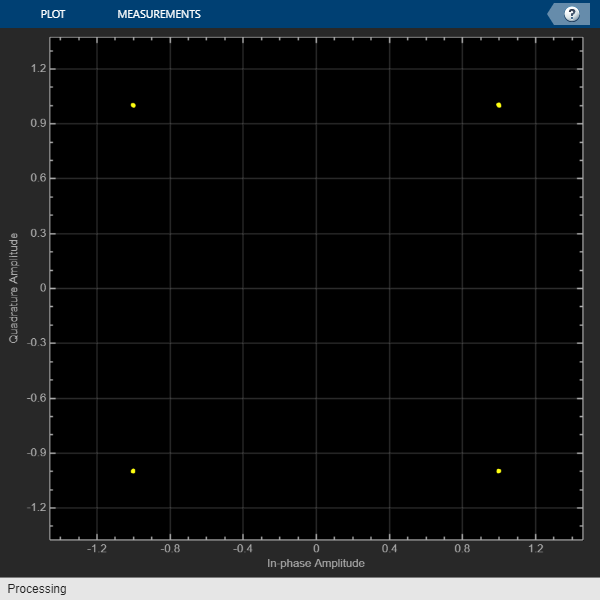


%Pass the signal through a noisy channel.
rxSig = awgn(txSig,50);
%Plot the constellation diagram.
cd = comm.ConstellationDiagram('ShowReferenceConstellation',false);
cd(rxSig)


z = qamdemod(rxSig,M,'bin','OutputType','bit');
s = isequal(data,double(z))

s = logical
   1


s

s = logical
   1



numBitErrors = numBits - sum(data == z);
numBitErrors

numBitErrors = 0


BER = numBitErrors/numBits; % the bit error rate (BER)
BER

BER = 0